# Furuta Pendulum: Phase 1 Open-Loop Model Validation (Downward & Upright Equilibria)

This Live Script validates the analytical linearized state-space models ($A_{\text{down}}, B_{\text{down}}$ at $\theta_1 = \pi$ and $A_{\text{up}}, B_{\text{up}}$ at $\theta_1 = 0$) and the full 3D nonlinear electromechanical ODE ($\dot{\mathbf{x}} = \mathbf{f}_{\text{nl}}(\mathbf{x}, V_a)$) directly against the Simscape Multibody digital twin (`robot_compatible.slx`), fulfilling Phase 1, Section 4.1.4.

**Validation Objectives:**

- **Small-angle consistency:** Confirm $\text{NRMSE}_{\theta_1} < 1\%$ between linear (`lsim`) and 3D nonlinear (`ode45`) trajectories at **both** the hanging downward equilibrium ($\theta_1 = \pi$) and the unstable upright apex ($\theta_1 = 0$).

- **Modal & parameter cross-check:** Recover downward oscillatory poles via logarithmic decrement and verify the upright unstable topple growth rate against  `plant.eig_upright`.

- **Nonlinear physics characterization:** Quantify large-angle gravitational period elongation ($60^\circ$ decay), **3D centrifugal flinging** ($\frac{1}{2}\hat{J}_1\sin(2\theta_1)\dot{\theta}_0^2$ under $1\text{ V}$ and $2\text{ V}$ steps), and the linear upright capture envelope.

- **3-Way Simscape Multibody overlay:** Overlay `simulate_simscape` directly onto Figures 1–4 against the Phase 1 $\text{NRMSE} < 3\%$ fidelity gate.

## 0. Workspace Setup & Scenario Catalog

Load SSOT parameters from `config/load_parameters.m`, build the unified linear and 3D nonlinear plant via `config/build_plant.m`, and generate the standardized 9-scenario open-loop catalog from `sim/scenarios/open_loop_scenarios.m`.

ensureProjectPaths();

params = load_parameters();
plant  = build_plant(params);
S      = open_loop_scenarios(params);
st     = validationPlotStyle();

% Set simscapeMode to "on" to overlay robot_compatible.slx on all figures,
% or "off" for fast analytical-only runs (always applied fresh on every run).
simscapeMode = "on";
runSimscape  = parseSimscapeMode(simscapeMode);

% Coordinate mapping for robot_compatible.slx (q_pend = 0 hangs down, +axis = -theta1)
ssCfg = struct( ...
    'ModelName',    "robot_compatible", ...
    'Theta1Sign',   -1.0, ...
    'Theta1Offset', pi);

fprintf('Loaded plant (L0 = %.4f m, l1 = %.4f m, Ts = %.1f ms, V_max = %.1f V, Simscape = %s)\n', ...
    params.L0, params.l1, params.Ts * 1e3, params.V_max, upper(simscapeMode));

Loaded plant (L0 = 0.0475 m, l1 = 0.0572 m, Ts = 2.0 ms, V_max = 12.0 V, Simscape = ON)


fprintf('Downward poles: %s\n', formatPoles(plant.eig_downward));

Downward poles: 0.000, -715.193, -0.185 +10.816j, -0.185 -10.816j


fprintf('Upright  poles: %s\n', formatPoles(plant.eig_upright));

Upright  poles: 0.000, -715.478, -10.858, 10.773


## 1. Downward Free Decay: Small-Angle Match ($5^\circ$) vs. Large-Angle Softening ($60^\circ$)

Near hanging rest ($\theta_1(0) = \pi + 5^\circ,\; V_a = 0$), $\sin\tilde{\theta}_1 \approx \tilde{\theta}_1$ and 3D centrifugal terms are second-order small, so linear and nonlinear trajectories overlay within $\text{NRMSE}_{\theta_1} \ll 1\%$ and logarithmic decrement directly recovers the coupled downward eigenvalues. At $60^\circ$, gravitational softening ($\sin 60^\circ \approx 0.866 < \pi/3$) elongates the nonlinear oscillation period ($T_{\text{nl}} > T_{\text{lin}}$), causing progressive phase-drift beating ($t\,e^{-\sigma t}$ residual envelope).

[r_dec5_lin,  r_dec5_nl,  r_dec5_ss,  m_dec5,  m_dec5_ss]  = runScenarioPair(S.decay_small, plant, params, runSimscape, ssCfg, true, false);
[r_dec60_lin, r_dec60_nl, r_dec60_ss, m_dec60, m_dec60_ss] = runScenarioPair(S.decay_large, plant, params, runSimscape, ssCfg, true, false);

oscPoles  = plant.eig_downward(abs(imag(plant.eig_downward)) > 1e-6);
sigma_eig = -real(oscPoles(1));
wd_eig    = abs(imag(oscPoles(1)));
zeta_eig  = sigma_eig / abs(oscPoles(1));

fprintf('Test 1A (5 deg decay):  Lin-vs-NL th1 NRMSE = %.4f%% (gate < %.1f%% -> %s), max err = %.4f deg\n', ...
    m_dec5.theta1_nrmse_pct, S.decay_small.nrmse_gate_pct, passStr(m_dec5.pass_gate), m_dec5.theta1_max_err_deg);

Test 1A (5 deg decay):  Lin-vs-NL th1 NRMSE = 0.1659% (gate < 1.0% -> PASS), max err = 0.0269 deg


fprintf('Log-Decrement ID (%d peaks): omega_d = %.4f rad/s (eig: %.4f), sigma = %.4f 1/s (eig: %.4f), zeta = %.4f (eig: %.4f)\n', ...
    m_dec5.damping.num_peaks, m_dec5.damping.omega_d, wd_eig, ...
    m_dec5.damping.sigma, sigma_eig, m_dec5.damping.zeta, zeta_eig);

Log-Decrement ID (11 peaks): omega_d = 10.8147 rad/s (eig: 10.8157), sigma = 0.1851 1/s (eig: 0.1851), zeta = 0.0171 (eig: 0.0171)


fprintf('Test 1B (60 deg decay): Lin-vs-NL th1 NRMSE = %.2f%%, max err = %.2f deg, T_d(nl) = %.4f s vs T_d(lin) = %.4f s\n', ...
    m_dec60.theta1_nrmse_pct, m_dec60.theta1_max_err_deg, m_dec60.damping.Td, 2*pi/wd_eig);

Test 1B (60 deg decay): Lin-vs-NL th1 NRMSE = 22.26%, max err = 43.81 deg, T_d(nl) = 0.5967 s vs T_d(lin) = 0.5809 s


if runSimscape
    fprintf('Simscape vs NL: 5 deg th1 NRMSE = %.2f%% | 60 deg th1 NRMSE = %.2f%%\n', ...
        m_dec5_ss.theta1_nrmse_pct, m_dec60_ss.theta1_nrmse_pct);
end

Simscape vs NL: 5 deg th1 NRMSE = 2.96% | 60 deg th1 NRMSE = 3.57%


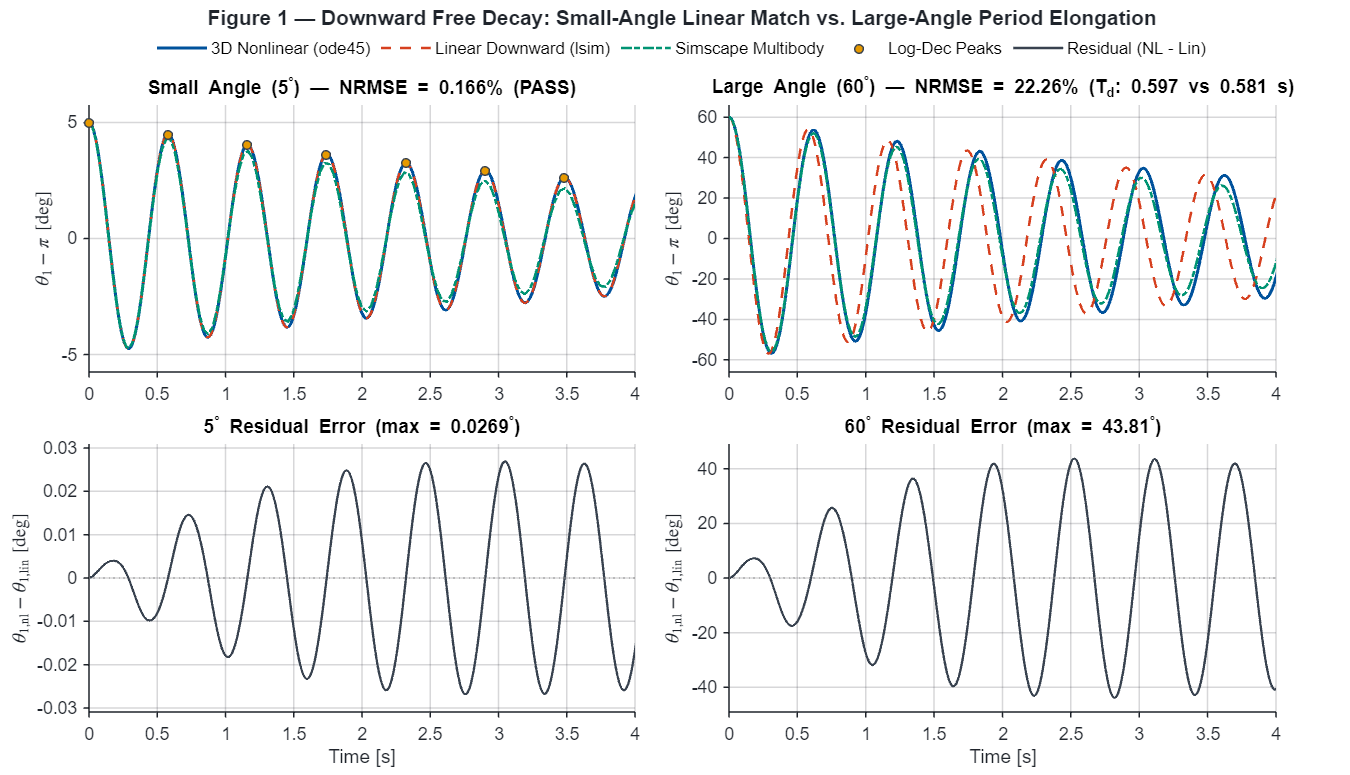


% Figure 1: Side-by-side 2x2 comparison (5 deg vs 60 deg over 0-4 s window)
tWin = 4.0;
fig1 = newStyledFigure('Figure 1: Downward Free Decay Comparison', [60, 60, 1080, 620]);
tl1  = tiledlayout(fig1, 2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
title(tl1, 'Figure 1 — Downward Free Decay: Small-Angle Linear Match vs. Large-Angle Period Elongation', ...
    'FontSize', st.superTitleFont, 'FontWeight', 'bold', 'Color', st.textColor);

% Top-left: 5 deg decay
ax11 = nexttile(tl1, 1);
hNL1  = plot(ax11, r_dec5_nl.t, rad2deg(r_dec5_nl.x(:, 3) - pi), '-', 'Color', st.nl, 'LineWidth', st.lwNL); hold(ax11, 'on');
hLin1 = plot(ax11, r_dec5_lin.t, rad2deg(r_dec5_lin.x(:, 3) - pi), '--', 'Color', st.lin, 'LineWidth', st.lwLin);
if runSimscape
    hSS1 = plot(ax11, r_dec5_ss.t, rad2deg(r_dec5_ss.x(:, 3) - pi), '-.', 'Color', st.teal, 'LineWidth', st.lwSS);
end
pkMask = m_dec5.damping.t_peaks <= tWin;
hPk1  = plot(ax11, m_dec5.damping.t_peaks(pkMask), rad2deg(m_dec5.damping.amp_peaks(pkMask)), ...
    'o', 'Color', st.slate, 'MarkerFaceColor', st.amber, 'MarkerSize', 5.2, 'LineWidth', 0.9);
xlim(ax11, [0, tWin]); setSymmetricYLim(ax11, [r_dec5_nl.x(:,3)-pi; r_dec5_lin.x(:,3)-pi], 1.15);
ylabel(ax11, '$\theta_1 - \pi\;[\mathrm{deg}]$', 'Interpreter', 'latex');
title(ax11, sprintf('Small Angle (5^\\circ) — NRMSE = %.3f%% (PASS)', m_dec5.theta1_nrmse_pct), 'FontSize', st.titleFont);
styleAxes(ax11, st);

% Top-right: 60 deg decay
ax12 = nexttile(tl1, 2);
plot(ax12, r_dec60_nl.t, rad2deg(r_dec60_nl.x(:, 3) - pi), '-', 'Color', st.nl, 'LineWidth', st.lwNL); hold(ax12, 'on');
plot(ax12, r_dec60_lin.t, rad2deg(r_dec60_lin.x(:, 3) - pi), '--', 'Color', st.lin, 'LineWidth', st.lwLin);
if runSimscape
    plot(ax12, r_dec60_ss.t, rad2deg(r_dec60_ss.x(:, 3) - pi), '-.', 'Color', st.teal, 'LineWidth', st.lwSS);
end
xlim(ax12, [0, tWin]); setSymmetricYLim(ax12, [r_dec60_nl.x(:,3)-pi; r_dec60_lin.x(:,3)-pi], 1.10);
ylabel(ax12, '$\theta_1 - \pi\;[\mathrm{deg}]$', 'Interpreter', 'latex');
title(ax12, sprintf('Large Angle (60^\\circ) — NRMSE = %.2f%% (T_d: %.3f vs %.3f s)', ...
    m_dec60.theta1_nrmse_pct, m_dec60.damping.Td, 2*pi/wd_eig), 'FontSize', st.titleFont);
styleAxes(ax12, st);

% Bottom-left: 5 deg residual error
ax21 = nexttile(tl1, 3);
err5 = rad2deg(r_dec5_nl.x(:, 3) - r_dec5_lin.x(:, 3));
hErr1 = plot(ax21, r_dec5_nl.t, err5, '-', 'Color', st.slate, 'LineWidth', 1.4);
yline(ax21, 0, ':', 'Color', [0.55, 0.55, 0.55], 'LineWidth', 0.9);
xlim(ax21, [0, tWin]); setSymmetricYLimDeg(ax21, err5(r_dec5_nl.t <= tWin), 1.15);
xlabel(ax21, 'Time [s]');
ylabel(ax21, '$\theta_{1,\mathrm{nl}} - \theta_{1,\mathrm{lin}}\;[\mathrm{deg}]$', 'Interpreter', 'latex');
title(ax21, sprintf('5^\\circ Residual Error (max = %.4f^\\circ)', m_dec5.theta1_max_err_deg), 'FontSize', st.titleFont);
styleAxes(ax21, st);

% Bottom-right: 60 deg residual error
ax22 = nexttile(tl1, 4);
err60 = rad2deg(r_dec60_nl.x(:, 3) - r_dec60_lin.x(:, 3));
plot(ax22, r_dec60_nl.t, err60, '-', 'Color', st.slate, 'LineWidth', 1.4);
yline(ax22, 0, ':', 'Color', [0.55, 0.55, 0.55], 'LineWidth', 0.9);
xlim(ax22, [0, tWin]); setSymmetricYLimDeg(ax22, err60(r_dec60_nl.t <= tWin), 1.12);
xlabel(ax22, 'Time [s]');
ylabel(ax22, '$\theta_{1,\mathrm{nl}} - \theta_{1,\mathrm{lin}}\;[\mathrm{deg}]$', 'Interpreter', 'latex');
title(ax22, sprintf('60^\\circ Residual Error (max = %.2f^\\circ)', m_dec60.theta1_max_err_deg), 'FontSize', st.titleFont);
styleAxes(ax22, st);

if runSimscape
    attachSharedLegend([hNL1, hLin1, hSS1, hPk1, hErr1], ...
        {'3D Nonlinear (ode45)', 'Linear Downward (lsim)', 'Simscape Multibody', 'Log-Dec Peaks', 'Residual (NL - Lin)'}, st);
else
    attachSharedLegend([hNL1, hLin1, hPk1, hErr1], ...
        {'3D Nonlinear (ode45)', 'Linear Downward (lsim)', 'Log-Dec Peaks', 'Residual (NL - Lin)'}, st);
end

## 2. Downward Open-Loop Voltage Steps ($0.2\text{ V} \to 1.0\text{ V} \to 2.0\text{ V}$): 3D Centrifugal Flinging

Starting from hanging rest ($\mathbf{x}_0 = [0, 0, \pi, 0]^T$), a positive voltage step accelerates the arm ($\ddot{\theta}_0 > 0$) and inertially kicks the pendulum ($B_{4,\text{down}} > 0 \implies \theta_1 - \pi > 0$). At small voltage ($0.2\text{ V}$), linear and nonlinear models agree within $< 1\%$. As step voltage increases to $1.0\text{ V}$ and $2.0\text{ V}$, sustained arm speed $\dot{\theta}_0$ activates the **3D centrifugal flinging torque** $+\frac{1}{2}\hat{J}_1\sin(2\theta_1)\dot{\theta}_0^2$, pulling the nonlinear pendulum further outward and elongating its swing period.

[r_st02_lin, r_st02_nl, r_st02_ss, m_st02, m_st02_ss] = runScenarioPair(S.step_small, plant, params, runSimscape, ssCfg, false, false);
[r_st1_lin,  r_st1_nl,  r_st1_ss,  m_st1,  m_st1_ss]  = runScenarioPair(S.step_1V,    plant, params, runSimscape, ssCfg, false, false);
[r_st2_lin,  r_st2_nl,  r_st2_ss,  m_st2,  m_st2_ss]  = runScenarioPair(S.step_2V,    plant, params, runSimscape, ssCfg, false, false);

pkLinDeg = [rad2deg(max(abs(r_st02_lin.x(:,3)-pi))), rad2deg(max(abs(r_st1_lin.x(:,3)-pi))), rad2deg(max(abs(r_st2_lin.x(:,3)-pi)))];
pkNlDeg  = [rad2deg(max(abs(r_st02_nl.x(:,3)-pi))),  rad2deg(max(abs(r_st1_nl.x(:,3)-pi))),  rad2deg(max(abs(r_st2_nl.x(:,3)-pi)))];
nrmseSt  = [m_st02.theta1_nrmse_pct, m_st1.theta1_nrmse_pct, m_st2.theta1_nrmse_pct];

fprintf('Step 0.2 V: Lin-vs-NL th1 NRMSE = %.4f%% (gate < %.1f%% -> %s), peak lin=%.2f vs nl=%.2f deg\n', ...
    m_st02.theta1_nrmse_pct, S.step_small.nrmse_gate_pct, passStr(m_st02.pass_gate), pkLinDeg(1), pkNlDeg(1));

Step 0.2 V: Lin-vs-NL th1 NRMSE = 0.4257% (gate < 1.0% -> PASS), peak lin=1.54 vs nl=1.54 deg


fprintf('Step 1.0 V: Lin-vs-NL th1 NRMSE = %.2f%%, peak lin=%.2f vs nl=%.2f deg (dth0 -> %.2f rad/s)\n', ...
    m_st1.theta1_nrmse_pct, pkLinDeg(2), pkNlDeg(2), r_st1_nl.x(end, 2));

Step 1.0 V: Lin-vs-NL th1 NRMSE = 10.40%, peak lin=7.68 vs nl=7.91 deg (dth0 -> 2.61 rad/s)


fprintf('Step 2.0 V: Lin-vs-NL th1 NRMSE = %.2f%%, peak lin=%.2f vs nl=%.2f deg (dth0 -> %.2f rad/s)\n', ...
    m_st2.theta1_nrmse_pct, pkLinDeg(3), pkNlDeg(3), r_st2_nl.x(end, 2));

Step 2.0 V: Lin-vs-NL th1 NRMSE = 36.06%, peak lin=15.35 vs nl=17.46 deg (dth0 -> 5.25 rad/s)


if runSimscape
    pkSsDeg = [rad2deg(max(abs(r_st02_ss.x(:,3)-pi))), rad2deg(max(abs(r_st1_ss.x(:,3)-pi))), rad2deg(max(abs(r_st2_ss.x(:,3)-pi)))];
    fprintf('Simscape vs NL: 0.2 V th1 NRMSE = %.2f%% | 1.0 V th1 NRMSE = %.2f%% | 2.0 V th1 NRMSE = %.2f%%\n', ...
        m_st02_ss.theta1_nrmse_pct, m_st1_ss.theta1_nrmse_pct, m_st2_ss.theta1_nrmse_pct);
end

Simscape vs NL: 0.2 V th1 NRMSE = 6.45% | 1.0 V th1 NRMSE = 6.82% | 2.0 V th1 NRMSE = 7.22%


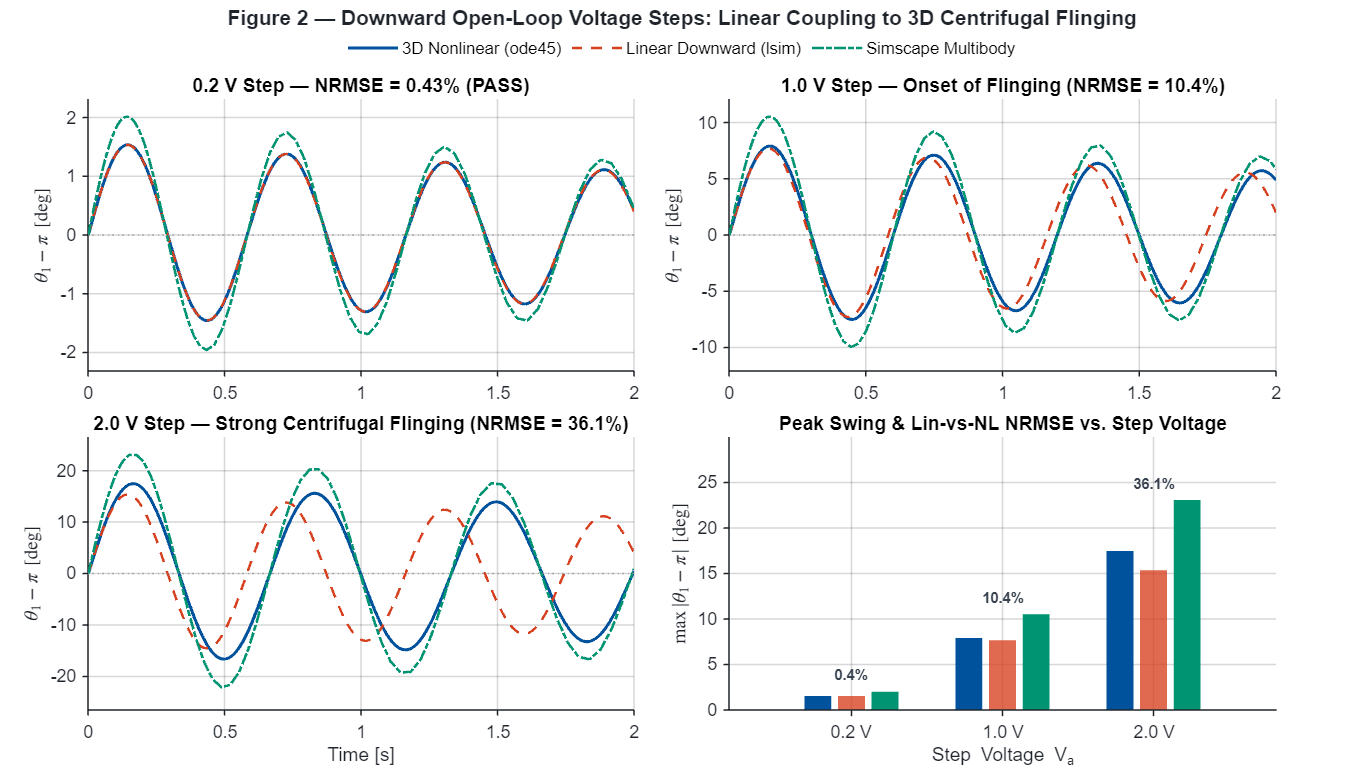


% Figure 2: 2x2 voltage progression (0.2 V, 1.0 V, 2.0 V + scale-invariant bar summary)
fig2 = newStyledFigure('Figure 2: Downward Voltage Steps & Centrifugal Flinging', [80, 80, 1080, 620]);
tl2  = tiledlayout(fig2, 2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
title(tl2, 'Figure 2 — Downward Open-Loop Voltage Steps: Linear Coupling to 3D Centrifugal Flinging', ...
    'FontSize', st.superTitleFont, 'FontWeight', 'bold', 'Color', st.textColor);

% Tile 1: 0.2 V Step
ax2a = nexttile(tl2, 1);
hNL2  = plot(ax2a, r_st02_nl.t, rad2deg(r_st02_nl.x(:, 3) - pi), '-', 'Color', st.nl, 'LineWidth', st.lwNL); hold(ax2a, 'on');
hLin2 = plot(ax2a, r_st02_lin.t, rad2deg(r_st02_lin.x(:, 3) - pi), '--', 'Color', st.lin, 'LineWidth', st.lwLin);
if runSimscape
    hSS2 = plot(ax2a, r_st02_ss.t, rad2deg(r_st02_ss.x(:, 3) - pi), '-.', 'Color', st.teal, 'LineWidth', st.lwSS);
    setSymmetricYLim(ax2a, [r_st02_nl.x(:,3)-pi; r_st02_lin.x(:,3)-pi; r_st02_ss.x(:,3)-pi], 1.15);
else
    setSymmetricYLim(ax2a, [r_st02_nl.x(:,3)-pi; r_st02_lin.x(:,3)-pi], 1.15);
end
yline(ax2a, 0, ':', 'Color', [0.55, 0.55, 0.55], 'LineWidth', 0.8);
ylabel(ax2a, '$\theta_1 - \pi\;[\mathrm{deg}]$', 'Interpreter', 'latex');
title(ax2a, sprintf('0.2 V Step — NRMSE = %.2f%% (PASS)', m_st02.theta1_nrmse_pct), 'FontSize', st.titleFont);
styleAxes(ax2a, st);

% Tile 2: 1.0 V Step
ax2b = nexttile(tl2, 2);
plot(ax2b, r_st1_nl.t, rad2deg(r_st1_nl.x(:, 3) - pi), '-', 'Color', st.nl, 'LineWidth', st.lwNL); hold(ax2b, 'on');
plot(ax2b, r_st1_lin.t, rad2deg(r_st1_lin.x(:, 3) - pi), '--', 'Color', st.lin, 'LineWidth', st.lwLin);
if runSimscape
    plot(ax2b, r_st1_ss.t, rad2deg(r_st1_ss.x(:, 3) - pi), '-.', 'Color', st.teal, 'LineWidth', st.lwSS);
    setSymmetricYLim(ax2b, [r_st1_nl.x(:,3)-pi; r_st1_lin.x(:,3)-pi; r_st1_ss.x(:,3)-pi], 1.15);
else
    setSymmetricYLim(ax2b, [r_st1_nl.x(:,3)-pi; r_st1_lin.x(:,3)-pi], 1.15);
end
yline(ax2b, 0, ':', 'Color', [0.55, 0.55, 0.55], 'LineWidth', 0.8);
ylabel(ax2b, '$\theta_1 - \pi\;[\mathrm{deg}]$', 'Interpreter', 'latex');
title(ax2b, sprintf('1.0 V Step — Onset of Flinging (NRMSE = %.1f%%)', m_st1.theta1_nrmse_pct), 'FontSize', st.titleFont);
styleAxes(ax2b, st);

% Tile 3: 2.0 V Step
ax2c = nexttile(tl2, 3);
plot(ax2c, r_st2_nl.t, rad2deg(r_st2_nl.x(:, 3) - pi), '-', 'Color', st.nl, 'LineWidth', st.lwNL); hold(ax2c, 'on');
plot(ax2c, r_st2_lin.t, rad2deg(r_st2_lin.x(:, 3) - pi), '--', 'Color', st.lin, 'LineWidth', st.lwLin);
if runSimscape
    plot(ax2c, r_st2_ss.t, rad2deg(r_st2_ss.x(:, 3) - pi), '-.', 'Color', st.teal, 'LineWidth', st.lwSS);
    setSymmetricYLim(ax2c, [r_st2_nl.x(:,3)-pi; r_st2_lin.x(:,3)-pi; r_st2_ss.x(:,3)-pi], 1.15);
else
    setSymmetricYLim(ax2c, [r_st2_nl.x(:,3)-pi; r_st2_lin.x(:,3)-pi], 1.15);
end
yline(ax2c, 0, ':', 'Color', [0.55, 0.55, 0.55], 'LineWidth', 0.8);
xlabel(ax2c, 'Time [s]');
ylabel(ax2c, '$\theta_1 - \pi\;[\mathrm{deg}]$', 'Interpreter', 'latex');
title(ax2c, sprintf('2.0 V Step — Strong Centrifugal Flinging (NRMSE = %.1f%%)', m_st2.theta1_nrmse_pct), 'FontSize', st.titleFont);
styleAxes(ax2c, st);

% Tile 4: Scale-invariant Peak Swing & NRMSE comparison across step voltages
ax2d = nexttile(tl2, 4);
xCat = categorical({'0.2 V', '1.0 V', '2.0 V'});
xCat = reordercats(xCat, {'0.2 V', '1.0 V', '2.0 V'});
if runSimscape
    barData2 = [pkNlDeg(:), pkLinDeg(:), pkSsDeg(:)];
    bGrp = bar(ax2d, xCat, barData2, 'grouped', 'EdgeColor', 'none');
    bGrp(1).FaceColor = st.nl;
    bGrp(2).FaceColor = st.lin; bGrp(2).FaceAlpha = 0.78;
    bGrp(3).FaceColor = st.teal;
else
    barData2 = [pkNlDeg(:), pkLinDeg(:)];
    bGrp = bar(ax2d, xCat, barData2, 'grouped', 'EdgeColor', 'none');
    bGrp(1).FaceColor = st.nl;
    bGrp(2).FaceColor = st.lin; bGrp(2).FaceAlpha = 0.78;
end
yTop2 = max(barData2(:)) * 1.30;
ylim(ax2d, [0, max(yTop2, 1e-3)]);
ylabel(ax2d, '$\max|\theta_1 - \pi|\;[\mathrm{deg}]$', 'Interpreter', 'latex');
xlabel(ax2d, 'Step Voltage V_a');
title(ax2d, 'Peak Swing & Lin-vs-NL NRMSE vs. Step Voltage', 'FontSize', st.titleFont);
styleAxes(ax2d, st);
placeBarLabels(ax2d, max(barData2, [], 2), arrayfun(@(v) sprintf('%.1f%%', v), nrmseSt, 'UniformOutput', false), st);

if runSimscape
    attachSharedLegend([hNL2, hLin2, hSS2], {'3D Nonlinear (ode45)', 'Linear Downward (lsim)', 'Simscape Multibody'}, st);
else
    attachSharedLegend([hNL2, hLin2], {'3D Nonlinear (ode45)', 'Linear Downward (lsim)'}, st);
end

## 3. Upright Mirror Validation ($\theta_{1,\text{eq}} = 0$): Topple Dynamics & $B_4 < 0$ Sign Flip

All Phase 2 stabilizing controllers (PID, Pole Placement, LQR) are synthesized from `plant.upright`. Mirroring the downward suite at the inverted apex confirms: (1) small-angle agreement ($\text{NRMSE}_{\theta_1} < 1\%$) and exponential topple rate matching the unstable RHP pole $\lambda_{\text{up}}$, (2) the $\approx 20^\circ$ linear capture envelope before linear blow-up departs from true nonlinear fall, and (3) the $c_{\text{eq}} = \pm 1$ input-coupling polarity reversal ($B_{4,\text{up}} < 0$ vs. $B_{4,\text{down}} > 0$).

[r_uf_s_lin, r_uf_s_nl, r_uf_s_ss, m_uf_s, m_uf_s_ss] = runScenarioPair(S.upright_fall_small, plant, params, runSimscape, ssCfg, false, true);
[r_uf_l_lin, r_uf_l_nl, r_uf_l_ss, m_uf_l, m_uf_l_ss] = runScenarioPair(S.upright_fall_large, plant, params, runSimscape, ssCfg, false, false);
[r_us02_lin, r_us02_nl, r_us02_ss, m_us02, m_us02_ss] = runScenarioPair(S.upright_step_small, plant, params, runSimscape, ssCfg, false, false);
[r_us1_lin,  r_us1_nl,  r_us1_ss,  m_us1,  m_us1_ss]  = runScenarioPair(S.upright_step_1V,    plant, params, runSimscape, ssCfg, false, false);

lambda_up_eig = max(real(plant.eig_upright));
fprintf('Test 3A (Upright fall 0.25 s): Lin-vs-NL th1 NRMSE = %.4f%% (gate < %.1f%% -> %s), topple rate = +%.3f vs eig +%.3f rad/s (R^2 = %.5f)\n', ...
    m_uf_s.theta1_nrmse_pct, S.upright_fall_small.nrmse_gate_pct, passStr(m_uf_s.pass_gate), ...
    m_uf_s.growth.lambda_hat, lambda_up_eig, m_uf_s.growth.r_squared);

Test 3A (Upright fall 0.25 s): Lin-vs-NL th1 NRMSE = 0.0687% (gate < 1.0% -> PASS), topple rate = +10.340 vs eig +10.773 rad/s (R^2 = 0.99983)


fprintf('Test 3B (Upright fall 0.60 s): linear = %.1f deg vs nonlinear = %.1f deg (NRMSE = %.2f%%)\n', ...
    rad2deg(r_uf_l_lin.x(end, 3)), rad2deg(r_uf_l_nl.x(end, 3)), m_uf_l.theta1_nrmse_pct);

Test 3B (Upright fall 0.60 s): linear = 652.2 deg vs nonlinear = 274.2 deg (NRMSE = 29.98%)


fprintf('Test 3C (Upright 0.2 V step):  theta1_end = %.2f deg (B4 < 0 sign flip), NRMSE = %.4f%% (gate < %.1f%% -> %s)\n', ...
    rad2deg(r_us02_nl.x(end, 3)), m_us02.theta1_nrmse_pct, S.upright_step_small.nrmse_gate_pct, passStr(m_us02.pass_gate));

Test 3C (Upright 0.2 V step):  theta1_end = -11.43 deg (B4 < 0 sign flip), NRMSE = 0.0388% (gate < 1.0% -> PASS)


fprintf('Test 3D (Upright 1.0 V step):  linear = %.1f deg vs nonlinear = %.1f deg (NRMSE = %.2f%%)\n', ...
    rad2deg(r_us1_lin.x(end, 3)), rad2deg(r_us1_nl.x(end, 3)), m_us1.theta1_nrmse_pct);

Test 3D (Upright 1.0 V step):  linear = -98.2 deg vs nonlinear = -96.2 deg (NRMSE = 0.61%)


if runSimscape
    fprintf('Simscape vs NL (Upright): fall_small = %.2f%% | fall_large = %.2f%% | step_0.2V = %.2f%% | step_1V = %.2f%%\n', ...
        m_uf_s_ss.theta1_nrmse_pct, m_uf_l_ss.theta1_nrmse_pct, m_us02_ss.theta1_nrmse_pct, m_us1_ss.theta1_nrmse_pct);
end

Simscape vs NL (Upright): fall_small = 1.62% | fall_large = 0.74% | step_0.2V = 10.92% | step_1V = 9.91%


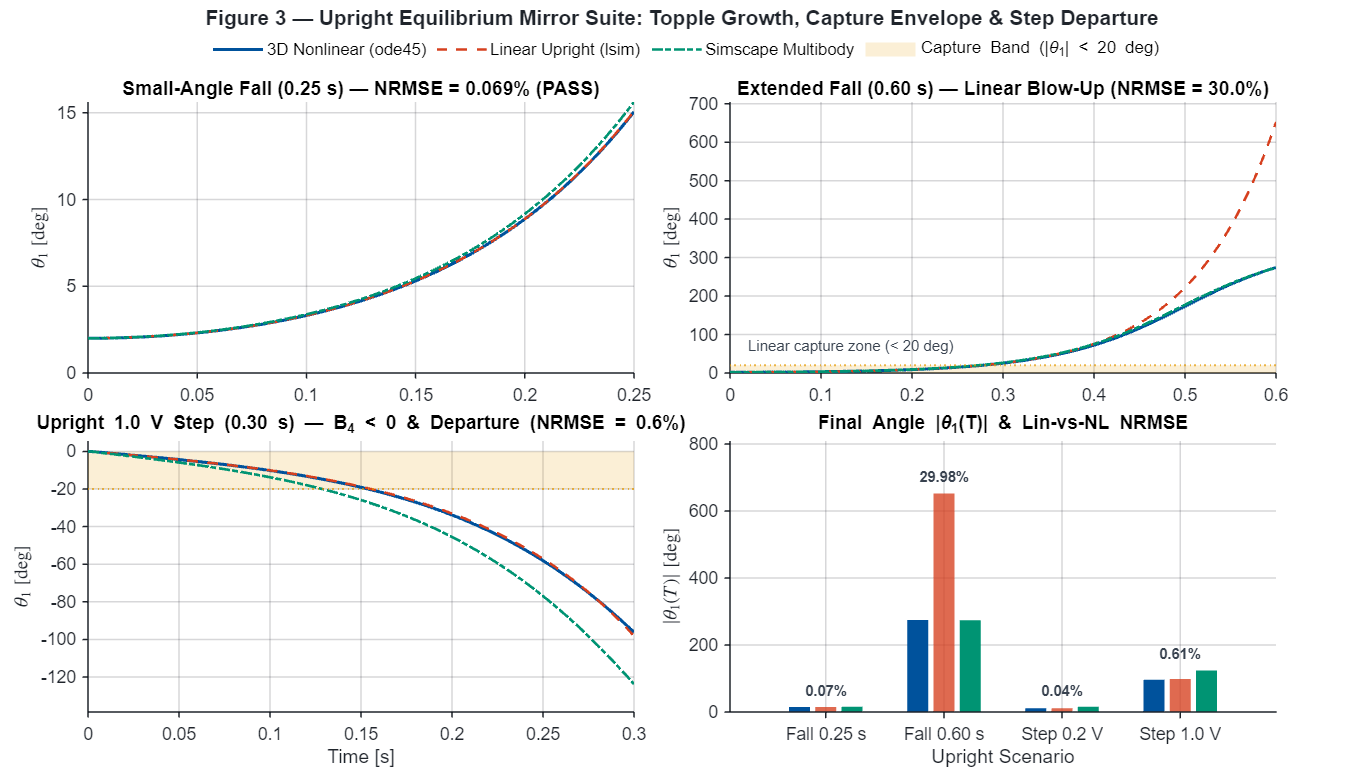


% Figure 3: 2x2 Upright mirror suite + scale-invariant final-angle/NRMSE bar chart
fig3 = newStyledFigure('Figure 3: Upright Mirror Validation & Final-Value Comparison', [100, 100, 1080, 620]);
tl3  = tiledlayout(fig3, 2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
title(tl3, 'Figure 3 — Upright Equilibrium Mirror Suite: Topple Growth, Capture Envelope & Step Departure', ...
    'FontSize', st.superTitleFont, 'FontWeight', 'bold', 'Color', st.textColor);

% Top-left: Small-angle upright fall (0.25 s)
ax31 = nexttile(tl3, 1);
hNL3  = plot(ax31, r_uf_s_nl.t, rad2deg(r_uf_s_nl.x(:, 3)), '-', 'Color', st.nl, 'LineWidth', st.lwNL); hold(ax31, 'on');
hLin3 = plot(ax31, r_uf_s_lin.t, rad2deg(r_uf_s_lin.x(:, 3)), '--', 'Color', st.lin, 'LineWidth', st.lwLin);
if runSimscape
    hSS3 = plot(ax31, r_uf_s_ss.t, rad2deg(r_uf_s_ss.x(:, 3)), '-.', 'Color', st.teal, 'LineWidth', st.lwSS);
end
xlim(ax31, [0, 0.25]);
ylabel(ax31, '$\theta_1\;[\mathrm{deg}]$', 'Interpreter', 'latex');
title(ax31, sprintf('Small-Angle Fall (0.25 s) — NRMSE = %.3f%% (PASS)', m_uf_s.theta1_nrmse_pct), 'FontSize', st.titleFont);
styleAxes(ax31, st);

% Top-right: Extended upright fall (0.60 s) with dynamic ylim & shaded capture band
ax32 = nexttile(tl3, 2);
hBand = patch(ax32, [0, 0.60, 0.60, 0], [0, 0, 20, 20], st.amber, 'FaceAlpha', 0.16, 'EdgeColor', 'none'); hold(ax32, 'on');
plot(ax32, r_uf_l_nl.t, rad2deg(r_uf_l_nl.x(:, 3)), '-', 'Color', st.nl, 'LineWidth', st.lwNL);
plot(ax32, r_uf_l_lin.t, rad2deg(r_uf_l_lin.x(:, 3)), '--', 'Color', st.lin, 'LineWidth', st.lwLin);
if runSimscape
    plot(ax32, r_uf_l_ss.t, rad2deg(r_uf_l_ss.x(:, 3)), '-.', 'Color', st.teal, 'LineWidth', st.lwSS);
end
yline(ax32, 20, ':', 'Color', st.amber, 'LineWidth', 1.2);
yMax32 = max(rad2deg([r_uf_l_nl.x(:,3); r_uf_l_lin.x(:,3)])) * 1.08;
xlim(ax32, [0, 0.60]); ylim(ax32, [0, yMax32]);
text(ax32, 0.02, 20 + 0.04 * yMax32, 'Linear capture zone (< 20 deg)', ...
    'FontSize', 9, 'Color', st.slate, 'VerticalAlignment', 'bottom', 'Clipping', 'on');
ylabel(ax32, '$\theta_1\;[\mathrm{deg}]$', 'Interpreter', 'latex');
title(ax32, sprintf('Extended Fall (0.60 s) — Linear Blow-Up (NRMSE = %.1f%%)', m_uf_l.theta1_nrmse_pct), 'FontSize', st.titleFont);
styleAxes(ax32, st);

% Bottom-left: Upright 1.0 V step with dynamic ylim & clipped capture band
ax33 = nexttile(tl3, 3);
us1Vals = rad2deg([r_us1_nl.x(:,3); r_us1_lin.x(:,3)]);
if runSimscape
    us1Vals = [us1Vals; rad2deg(r_us1_ss.x(:,3))];
end
yMin33 = min(min(us1Vals) * 1.12, -24);
patch(ax33, [0, 0.30, 0.30, 0], [0, 0, -20, -20], st.amber, 'FaceAlpha', 0.16, 'EdgeColor', 'none'); hold(ax33, 'on');
plot(ax33, r_us1_nl.t, rad2deg(r_us1_nl.x(:, 3)), '-', 'Color', st.nl, 'LineWidth', st.lwNL);
plot(ax33, r_us1_lin.t, rad2deg(r_us1_lin.x(:, 3)), '--', 'Color', st.lin, 'LineWidth', st.lwLin);
if runSimscape
    plot(ax33, r_us1_ss.t, rad2deg(r_us1_ss.x(:, 3)), '-.', 'Color', st.teal, 'LineWidth', st.lwSS);
end
yline(ax33, -20, ':', 'Color', st.amber, 'LineWidth', 1.2);
xlim(ax33, [0, 0.30]); ylim(ax33, [yMin33, 0.04 * abs(yMin33)]);
xlabel(ax33, 'Time [s]');
ylabel(ax33, '$\theta_1\;[\mathrm{deg}]$', 'Interpreter', 'latex');
title(ax33, sprintf('Upright 1.0 V Step (0.30 s) — B_4 < 0 & Departure (NRMSE = %.1f%%)', m_us1.theta1_nrmse_pct), 'FontSize', st.titleFont);
styleAxes(ax33, st);

% Bottom-right: Scale-invariant Final Angle |theta1(T)| & NRMSE comparison
ax34 = nexttile(tl3, 4);
upCats = categorical({'Fall 0.25 s', 'Fall 0.60 s', 'Step 0.2 V', 'Step 1.0 V'});
upCats = reordercats(upCats, {'Fall 0.25 s', 'Fall 0.60 s', 'Step 0.2 V', 'Step 1.0 V'});
upFinalNl  = abs(rad2deg([r_uf_s_nl.x(end,3),  r_uf_l_nl.x(end,3),  r_us02_nl.x(end,3),  r_us1_nl.x(end,3)]));
upFinalLin = abs(rad2deg([r_uf_s_lin.x(end,3), r_uf_l_lin.x(end,3), r_us02_lin.x(end,3), r_us1_lin.x(end,3)]));
upNrmse    = [m_uf_s.theta1_nrmse_pct, m_uf_l.theta1_nrmse_pct, m_us02.theta1_nrmse_pct, m_us1.theta1_nrmse_pct];

if runSimscape
    upFinalSs = abs(rad2deg([r_uf_s_ss.x(end,3), r_uf_l_ss.x(end,3), r_us02_ss.x(end,3), r_us1_ss.x(end,3)]));
    barData3  = [upFinalNl(:), upFinalLin(:), upFinalSs(:)];
    bUp = bar(ax34, upCats, barData3, 'grouped', 'EdgeColor', 'none');
    bUp(1).FaceColor = st.nl;
    bUp(2).FaceColor = st.lin; bUp(2).FaceAlpha = 0.78;
    bUp(3).FaceColor = st.teal;
else
    barData3 = [upFinalNl(:), upFinalLin(:)];
    bUp = bar(ax34, upCats, barData3, 'grouped', 'EdgeColor', 'none');
    bUp(1).FaceColor = st.nl;
    bUp(2).FaceColor = st.lin; bUp(2).FaceAlpha = 0.78;
end
yTop3 = max(barData3(:)) * 1.24;
ylim(ax34, [0, max(yTop3, 1.0)]);
ylabel(ax34, '$|\theta_1(T)|\;[\mathrm{deg}]$', 'Interpreter', 'latex');
xlabel(ax34, 'Upright Scenario');
title(ax34, 'Final Angle |\theta_1(T)| & Lin-vs-NL NRMSE', 'FontSize', st.titleFont);
styleAxes(ax34, st);
placeBarLabels(ax34, max(barData3, [], 2), arrayfun(@(v) sprintf('%.2f%%', v), upNrmse, 'UniformOutput', false), st);

if runSimscape
    attachSharedLegend([hNL3, hLin3, hSS3, hBand], ...
        {'3D Nonlinear (ode45)', 'Linear Upright (lsim)', 'Simscape Multibody', 'Capture Band (|\theta_1| < 20 deg)'}, st);
else
    attachSharedLegend([hNL3, hLin3, hBand], ...
        {'3D Nonlinear (ode45)', 'Linear Upright (lsim)', 'Capture Band (|\theta_1| < 20 deg)'}, st);
end

## 4. Cross-Scenario Validation Dashboard & Summary Table

Aggregate all 9 scenarios (5 downward + 4 upright mirror) into two explicit validation gates: (1) **Linear vs. 3D Nonlinear** ($< 1\%$ on small-angle runs, N/A on large-angle nonlinear showcases) and (2) **Simscape vs. 3D Nonlinear** ($< 3\%$ Phase 1 fidelity gate enforced as strict PASS/FAIL on all 9 runs).

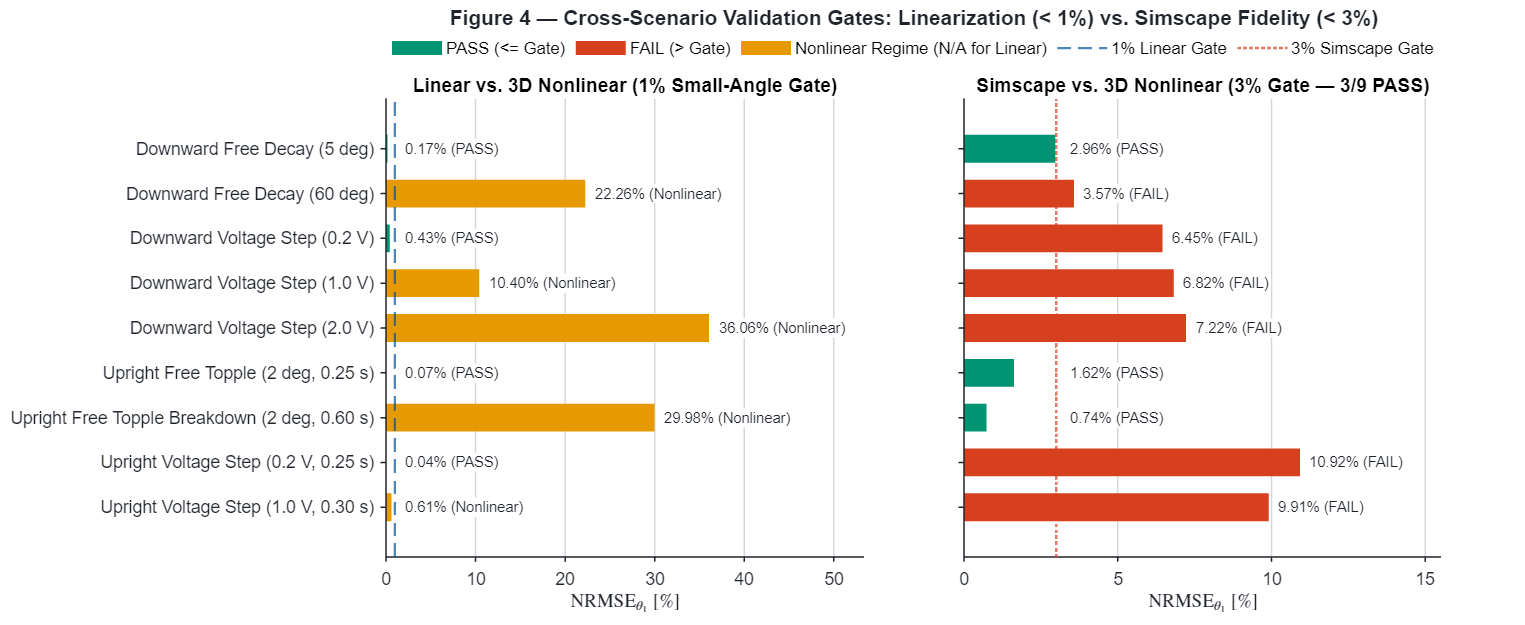

allScenarios = { ...
    S.decay_small, S.decay_large, S.step_small, S.step_1V, S.step_2V, ...
    S.upright_fall_small, S.upright_fall_large, S.upright_step_small, S.upright_step_1V};
allMetrics   = {m_dec5, m_dec60, m_st02, m_st1, m_st2, m_uf_s, m_uf_l, m_us02, m_us1};
allSsMetrics = {m_dec5_ss, m_dec60_ss, m_st02_ss, m_st1_ss, m_st2_ss, m_uf_s_ss, m_uf_l_ss, m_us02_ss, m_us1_ss};

nSc          = numel(allScenarios);
Scenario     = strings(nSc, 1);
Equilibrium  = strings(nSc, 1);
Lin_Th0_Pct  = zeros(nSc, 1);
Lin_Th1_Pct  = zeros(nSc, 1);
Lin_Gate_Pct = zeros(nSc, 1);
Lin_Status   = strings(nSc, 1);
SS_Th0_Pct   = nan(nSc, 1);
SS_Th1_Pct   = nan(nSc, 1);
SS_Gate_Pct  = zeros(nSc, 1);
SS_Status    = strings(nSc, 1);

for k = 1:nSc
    sc = allScenarios{k};
    mk = allMetrics{k};
    Scenario(k)     = string(sc.name);
    Equilibrium(k)  = sc.equilibrium;
    Lin_Th0_Pct(k)  = mk.theta0_nrmse_pct;
    Lin_Th1_Pct(k)  = mk.theta1_nrmse_pct;
    Lin_Gate_Pct(k) = sc.nrmse_gate_pct;
    SS_Gate_Pct(k)  = sc.simscape_gate_pct;

    if isnan(sc.nrmse_gate_pct)
        Lin_Status(k) = "N/A (Nonlinear)";
    elseif mk.pass_gate
        Lin_Status(k) = "PASS";
    else
        Lin_Status(k) = "FAIL";
    end

    if runSimscape && ~isempty(allSsMetrics{k})
        mks = allSsMetrics{k};
        SS_Th0_Pct(k) = mks.theta0_nrmse_pct;
        SS_Th1_Pct(k) = mks.theta1_nrmse_pct;
        if mks.pass_gate
            SS_Status(k) = "PASS";
        else
            SS_Status(k) = "FAIL";
        end
    else
        SS_Status(k) = "SKIPPED";
    end
end

if runSimscape
    valTable = table(Scenario, Equilibrium, Lin_Th1_Pct, Lin_Status, ...
        SS_Th0_Pct, SS_Th1_Pct, SS_Status, ...
        'VariableNames', {'Scenario', 'Equilibrium', 'Lin_NL_Th1_Pct', 'Lin_Status', ...
        'SS_NL_Th0_Pct', 'SS_NL_Th1_Pct', 'SS_Status'});
else
    valTable = table(Scenario, Equilibrium, Lin_Th0_Pct, Lin_Th1_Pct, Lin_Gate_Pct, Lin_Status, ...
        'VariableNames', {'Scenario', 'Equilibrium', 'Lin_NL_Th0_Pct', 'Lin_NL_Th1_Pct', ...
        'Lin_Gate_Pct', 'Lin_Status'});
end

% Figure 4: Split 1x2 Cross-Scenario NRMSE Validation Dashboard
yIdx = 1:nSc;
if runSimscape
    fig4 = newStyledFigure('Figure 4: Cross-Scenario NRMSE Validation Dashboard', [60, 100, 1220, 500]);
    tl4  = tiledlayout(fig4, 1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
    title(tl4, 'Figure 4 — Cross-Scenario Validation Gates: Linearization (< 1%) vs. Simscape Fidelity (< 3%)', ...
        'FontSize', st.superTitleFont, 'FontWeight', 'bold', 'Color', st.textColor);

    % Left Panel: Linear vs. 3D Nonlinear (1% small-angle gate)
    ax4L = nexttile(tl4, 1);
    bLin = barh(ax4L, yIdx, Lin_Th1_Pct, 0.62, 'FaceColor', 'flat', 'EdgeColor', 'none'); hold(ax4L, 'on');
    for k = 1:nSc
        if Lin_Status(k) == "PASS"
            bLin.CData(k, :) = st.teal;
        elseif Lin_Status(k) == "FAIL"
            bLin.CData(k, :) = st.lin;
        else
            bLin.CData(k, :) = st.amber;
        end
    end
    hG1  = xline(ax4L, 1.0, '--', 'Color', st.nl, 'LineWidth', 1.35);
    maxXL = max([Lin_Th1_Pct; 4.0], [], 'omitnan') * 1.48;
    set(ax4L, 'YTick', yIdx, 'YTickLabel', cellstr(Scenario), 'YDir', 'reverse');
    xlim(ax4L, [0, maxXL]);
    xlabel(ax4L, '$\mathrm{NRMSE}_{\theta_1}\;[\%]$', 'Interpreter', 'latex');
    title(ax4L, 'Linear vs. 3D Nonlinear (1% Small-Angle Gate)', 'FontSize', st.titleFont);
    styleAxes(ax4L, st);
    ax4L.YGrid = 'off';
    for k = 1:nSc
        if Lin_Status(k) == "N/A (Nonlinear)"
            lblL = sprintf('%.2f%% (Nonlinear)', Lin_Th1_Pct(k));
        else
            lblL = sprintf('%.2f%% (%s)', Lin_Th1_Pct(k), Lin_Status(k));
        end
        xTxtL = max(Lin_Th1_Pct(k), 1.1) + 0.02 * maxXL;
        text(ax4L, xTxtL, k, lblL, 'VerticalAlignment', 'middle', 'FontSize', 8.8, ...
            'Color', st.textColor, 'BackgroundColor', 'w', 'Margin', 1, 'Clipping', 'on');
    end

    % Right Panel: Simscape vs. 3D Nonlinear (3% Phase 1 gate on ALL 9 scenarios)
    ax4R = nexttile(tl4, 2);
    bSS  = barh(ax4R, yIdx, SS_Th1_Pct, 0.62, 'FaceColor', 'flat', 'EdgeColor', 'none'); hold(ax4R, 'on');
    for k = 1:nSc
        if SS_Status(k) == "PASS"
            bSS.CData(k, :) = st.teal;
        else
            bSS.CData(k, :) = st.lin;
        end
    end
    hG3  = xline(ax4R, 3.0, ':', 'Color', st.lin, 'LineWidth', 1.5);
    maxXR = max([SS_Th1_Pct; 5.0], [], 'omitnan') * 1.42;
    set(ax4R, 'YTick', yIdx, 'YTickLabel', {}, 'YDir', 'reverse');
    xlim(ax4R, [0, maxXR]);
    xlabel(ax4R, '$\mathrm{NRMSE}_{\theta_1}\;[\%]$', 'Interpreter', 'latex');
    title(ax4R, sprintf('Simscape vs. 3D Nonlinear (3%% Gate — %d/%d PASS)', ...
        sum(SS_Status == "PASS"), nSc), 'FontSize', st.titleFont);
    styleAxes(ax4R, st);
    ax4R.YGrid = 'off';
    for k = 1:nSc
        lblR  = sprintf('%.2f%% (%s)', SS_Th1_Pct(k), SS_Status(k));
        xTxtR = max(SS_Th1_Pct(k), 3.15 * (SS_Status(k) == "PASS")) + 0.02 * maxXR;
        text(ax4R, xTxtR, k, lblR, 'VerticalAlignment', 'middle', 'FontSize', 8.8, ...
            'Color', st.textColor, 'BackgroundColor', 'w', 'Margin', 1, 'Clipping', 'on');
    end

    hPass = barh(ax4L, NaN, NaN, 'FaceColor', st.teal,  'EdgeColor', 'none');
    hFail = barh(ax4L, NaN, NaN, 'FaceColor', st.lin,   'EdgeColor', 'none');
    hShow = barh(ax4L, NaN, NaN, 'FaceColor', st.amber, 'EdgeColor', 'none');
    attachSharedLegend([hPass, hFail, hShow, hG1, hG3], ...
        {'PASS (<= Gate)', 'FAIL (> Gate)', 'Nonlinear Regime (N/A for Linear)', '1% Linear Gate', '3% Simscape Gate'}, st);
else
    fig4 = newStyledFigure('Figure 4: Cross-Scenario NRMSE Validation Dashboard', [120, 120, 1020, 490]);
    tl4  = tiledlayout(fig4, 1, 1, 'Padding', 'compact');
    title(tl4, 'Figure 4 — Cross-Scenario Pendulum NRMSE Comparison (Linear vs. 3D Nonlinear)', ...
        'FontSize', st.superTitleFont, 'FontWeight', 'bold', 'Color', st.textColor);
    ax4L = nexttile(tl4, 1);
    bLin = barh(ax4L, yIdx, Lin_Th1_Pct, 0.62, 'FaceColor', 'flat', 'EdgeColor', 'none'); hold(ax4L, 'on');
    for k = 1:nSc
        if Lin_Status(k) == "PASS"
            bLin.CData(k, :) = st.teal;
        elseif Lin_Status(k) == "FAIL"
            bLin.CData(k, :) = st.lin;
        else
            bLin.CData(k, :) = st.amber;
        end
    end
    hG1  = xline(ax4L, 1.0, '--', 'Color', st.nl, 'LineWidth', 1.35);
    maxXL = max([Lin_Th1_Pct; 4.0], [], 'omitnan') * 1.35;
    set(ax4L, 'YTick', yIdx, 'YTickLabel', cellstr(Scenario), 'YDir', 'reverse');
    xlim(ax4L, [0, maxXL]);
    xlabel(ax4L, '$\mathrm{NRMSE}_{\theta_1}\;[\%]$', 'Interpreter', 'latex');
    styleAxes(ax4L, st);
    ax4L.YGrid = 'off';
    for k = 1:nSc
        xTxtL = max(Lin_Th1_Pct(k), 1.1) + 0.015 * maxXL;
        text(ax4L, xTxtL, k, sprintf('%.2f%% (%s)', Lin_Th1_Pct(k), Lin_Status(k)), ...
            'VerticalAlignment', 'middle', 'FontSize', 8.8, 'Color', st.textColor, ...
            'BackgroundColor', 'w', 'Margin', 1, 'Clipping', 'on');
    end
    hPass = barh(ax4L, NaN, NaN, 'FaceColor', st.teal,  'EdgeColor', 'none');
    hShow = barh(ax4L, NaN, NaN, 'FaceColor', st.amber, 'EdgeColor', 'none');
    attachSharedLegend([hPass, hShow, hG1], ...
        {'Small-Angle Gate PASS (< 1%)', 'Nonlinear Regime (N/A)', '1% Linear Validity Gate'}, st);
end


disp(valTable);

                       Scenario                        Equilibrium    Lin_NL_Th1_Pct       Lin_Status        SS_NL_Th0_Pct    SS_NL_Th1_Pct    SS_Status
    _______________________________________________    ___________    ______________    _________________    _____________    _____________    _________

    "Downward Free Decay (5 deg)"                      "downward"         0.16594       "PASS"                   4.3452           2.964         "PASS"  
    "Downward Free Decay (60 deg)"                     "downward"          22.257       "N/A (Nonlinear)"        4.8772          3.5724         "FAIL"  
    "Downward Voltage Step (0.2 V)"                    "downward"         0.42572       "PASS"                 0.044947          6.4503         "FAIL

nLinChecked = sum(~isnan(Lin_Gate_Pct));
nLinPass    = sum(Lin_Status == "PASS");
fprintf('[Summary] Linear Validity Gate (< 1.0%%, small-angle): %d / %d PASS\n', nLinPass, nLinChecked);

[Summary] Linear Validity Gate (< 1.0%, small-angle): 4 / 4 PASS


if runSimscape
    nSsPass = sum(SS_Status == "PASS");
    nSsFail = sum(SS_Status == "FAIL");
    fprintf('[Summary] Simscape Fidelity Gate (< 3.0%%, all runs):  %d / %d PASS (%d FAIL)\n', nSsPass, nSc, nSsFail);
end

[Summary] Simscape Fidelity Gate (< 3.0%, all runs):  3 / 9 PASS (6 FAIL)


## Local Helper Functions

function tf = parseSimscapeMode(modeStr)
    tf = strcmpi(string(modeStr), "on");
end

function [r_lin, r_nl, r_ss, m_lin, m_ss] = runScenarioPair(sc, plant, params, runSimscape, ssCfg, estDamp, estGrowth)
    r_lin = simulate_linear(plant, sc.x0, sc.t_grid, sc.u_spec, Equilibrium=sc.equilibrium);
    r_nl  = simulate_nonlinear(plant, params, sc.x0, sc.t_grid, sc.u_spec);
    m_lin = compute_validation_metrics(r_nl, r_lin, ...
        NrmseGatePct=sc.nrmse_gate_pct, EstimateDamping=estDamp, ...
        EstimateGrowthRate=estGrowth, Params=params);

    if runSimscape
        r_ss = simulate_simscape(params, sc.x0, sc.t_grid, sc.u_spec, ...
            ModelName=ssCfg.ModelName, Theta1Sign=ssCfg.Theta1Sign, ...
            Theta1Offset=ssCfg.Theta1Offset, UseExternalInput=true);
        m_ss = compute_validation_metrics(r_ss, r_nl, NrmseGatePct=sc.simscape_gate_pct);
    else
        r_ss = struct();
        m_ss = struct();
    end
end

function st = validationPlotStyle()
    % Centralized colorblind-safe Okabe-Ito / publication palette
    st = struct();
    st.nl             = [0.00, 0.32, 0.61];  % Deep navy (3D Nonlinear)
    st.lin            = [0.84, 0.25, 0.12];  % Vermilion (Linearized)
    st.teal           = [0.00, 0.58, 0.45];  % Teal (Simscape Multibody / PASS)
    st.amber          = [0.90, 0.60, 0.00];  % Warm amber (Showcases / Peaks / Capture zone)
    st.slate          = [0.22, 0.26, 0.31];  % Dark slate (Residuals & annotations)
    st.textColor      = [0.12, 0.14, 0.17];
    st.lwNL           = 1.85;
    st.lwLin          = 1.50;
    st.lwSS           = 1.60;
    st.axisFont       = 10.5;
    st.titleFont      = 11.0;
    st.superTitleFont = 12.5;
end

function fig = newStyledFigure(figName, pos)
    fig = figure('Name', figName, 'Color', 'w', 'Position', pos);
end

function styleAxes(ax, st)
    box(ax, 'off');
    grid(ax, 'on');
    ax.GridAlpha  = 0.18;
    ax.FontSize   = st.axisFont;
    ax.LineWidth  = 0.9;
    ax.TickDir    = 'out';
    ax.XColor     = st.textColor;
    ax.YColor     = st.textColor;
end

function setSymmetricYLim(ax, radVals, padFactor)
    setSymmetricYLimDeg(ax, rad2deg(radVals), padFactor);
end

function setSymmetricYLimDeg(ax, degVals, padFactor)
    mVal = max(abs(degVals(:)));
    if ~isfinite(mVal) || mVal < 1e-6
        mVal = 1.0;
    end
    ylim(ax, [-mVal * padFactor, mVal * padFactor]);
end

function placeBarLabels(ax, barTops, labels, st)
    yLims = ylim(ax);
    yPad  = 0.03 * diff(yLims);
    for k = 1:numel(barTops)
        text(ax, k, barTops(k) + yPad, labels{k}, ...
            'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', ...
            'FontSize', 8.8, 'FontWeight', 'bold', 'Color', st.slate, 'Clipping', 'on');
    end
end

function attachSharedLegend(handles, labels, st)
    lgd = legend(handles, labels, 'Orientation', 'horizontal', ...
        'Box', 'off', 'FontSize', st.axisFont - 0.5);
    lgd.Layout.Tile = 'north';
end

function ensureProjectPaths()
    if exist('load_parameters', 'file') && exist('simulate_linear', 'file') ...
            && exist('open_loop_scenarios', 'file') && exist('compute_validation_metrics', 'file') ...
            && exist('robot_compatible', 'file') && exist('arm_visual.stl', 'file')
        return;
    end
    cur = pwd;
    for k = 1:6
        if exist(fullfile(cur, 'startup.m'), 'file')
            addpath(fullfile(cur, 'config'));
            addpath(fullfile(cur, 'sim', 'runners'));
            addpath(fullfile(cur, 'sim', 'scenarios'));
            addpath(fullfile(cur, 'digital-twin', 'validation'));
            addpath(fullfile(cur, 'digital-twin', 'models', 'simscape'));
            addpath(fullfile(cur, 'digital-twin', 'models', 'simscape', 'stl'));
            return;
        end
        parent = fileparts(cur);
        if strcmp(parent, cur), break; end
        cur = parent;
    end
    error('Furuta:RepoRootNotFound', 'Could not locate repository root containing startup.m.');
end

function s = passStr(tf)
    if tf
        s = 'PASS';
    else
        s = 'FAIL';
    end
end

function s = formatPoles(p)
    parts = strings(numel(p), 1);
    for k = 1:numel(p)
        if abs(imag(p(k))) < 1e-9
            parts(k) = sprintf('%.3f', real(p(k)));
        else
            parts(k) = sprintf('%.3f %+.3fj', real(p(k)), imag(p(k)));
        end
    end
    s = strjoin(parts, ', ');
end